clear
clc

# A)

## Checking controllability and observability of the system

Ag=[0 1 0 0 0;-0.1 -0.5 0 0 0;0.5 0 0 0 0;0 0 10 0 0;0.5 1 0 0 0]

Ag =          0    1.0000         0         0         0
   -0.1000   -0.5000         0         0         0
    0.5000         0         0         0         0
         0         0   10.0000         0         0
    0.5000    1.0000         0         0         0


Bg=[0 1 0 0 0]'

Bg =      0
     1
     0
     0
     0


Cg=[0 0 0 1 0]

Cg =      0     0     0     1     0


Dg=0

Dg = 0


system_order = length(Ag)

system_order = 5

M = ctrb(Ag, Bg);
rank_of_M = rank(M)

rank_of_M = 4

N = obsv(Ag, Cg);
rank_of_N = rank(N)

rank_of_N = 4

### The uncontrollable state indicates that M and N does not have full rank of system_order therefore the system is not controllable and observable

# B) 

## Developing a controllable state variable model

[NUM,DEN] = ss2tf(Ag,Bg,Cg,Dg)

NUM =          0         0         0         0    5.0000         0


DEN =     1.0000    0.5000    0.1000         0         0         0


After canceling common factor z

NUM=[0 0 0 0 5];
DEN=[1 0.5 0.1 0 0];
[Ag, Bg, Cg, Dg] = tf2ss(NUM, DEN)

Ag =    -0.5000   -0.1000         0         0
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


Bg =      1
     0
     0
     0


Cg =      0     0     0     5


Dg = 0

# C)

Checking controllability and observability

system_order = length(Ag)

system_order = 4

M = ctrb(Ag, Bg);
rank_of_M = rank(M)

rank_of_M = 4

N = obsv(Ag, Cg);
rank_of_N = rank(N)

rank_of_N = 4

The system is controllable because the M and N matrices have the same rank as the system.

# D)

sys=tf(NUM,DEN)

sys =
 
             5
  -----------------------
  s^4 + 0.5 s^3 + 0.1 s^2
 
Continuous-time transfer function.



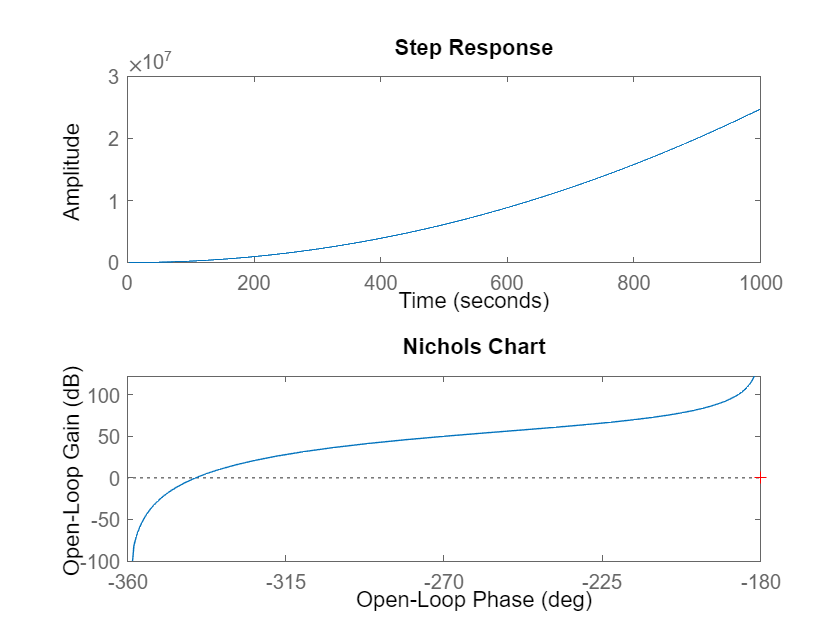

subplot(211)
step(sys)
subplot(212)
nichols(sys)

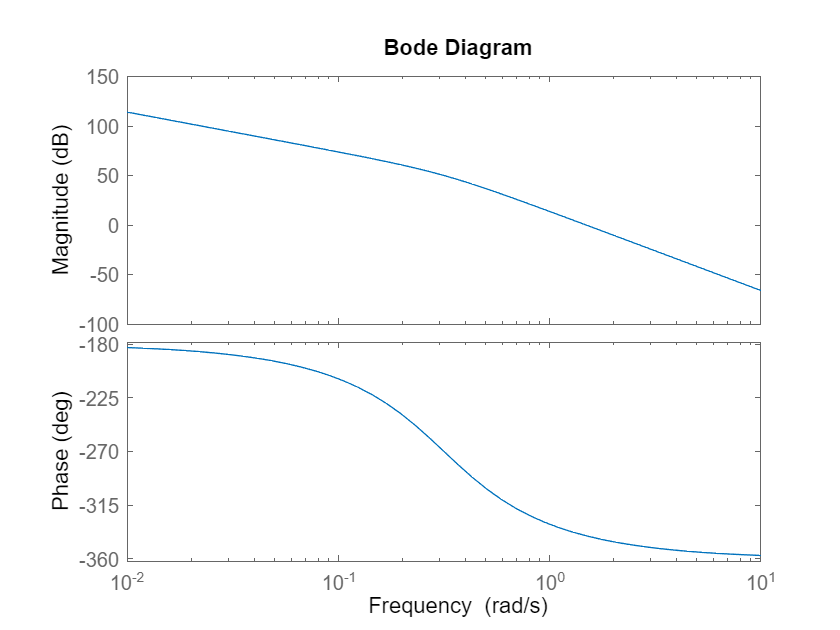

figure
bode(sys)

System is unstable

new_desired_poles = [-0.25+0.25i -0.25-0.25i -0.5+0.5i -0.5-0.5i];

new_desired_poles =   -0.2500 + 0.2500i  -0.2500 - 0.2500i  -0.5000 + 0.5000i  -0.5000 - 0.5000i
